# Von Daten zu Wissen

## Zufallsdaten: Normalverteilung

Erzeugen Sie einen Vector v mit 100 Datenelemente mit randn und zeichnen Sie ein Histrogramm.

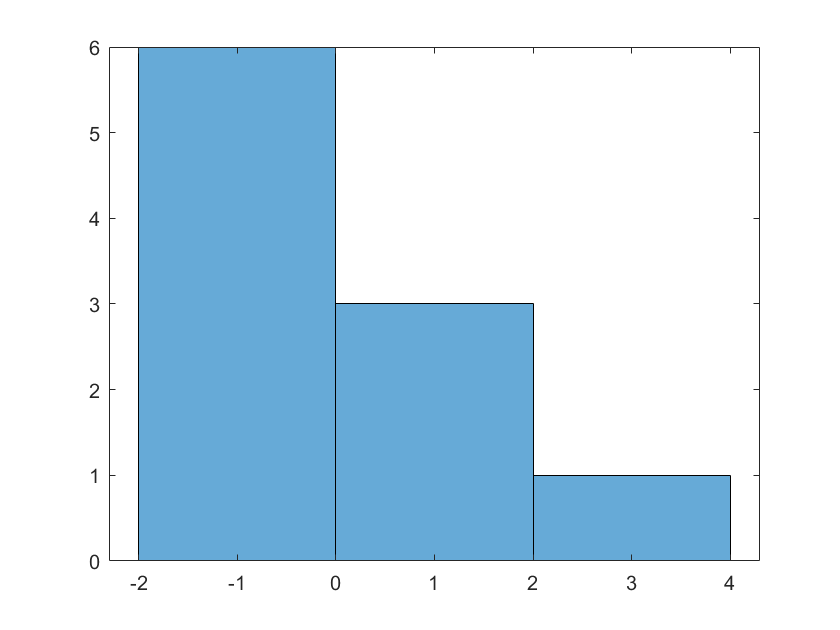

v = randn(1,10);
histogram(v);

Erzeugen Sie einen Vector v mit 100000 Datenelement mit randn und zeichnen Sie ein Histogramm. Wie unterscheiden Sie die zwei Histogramme?

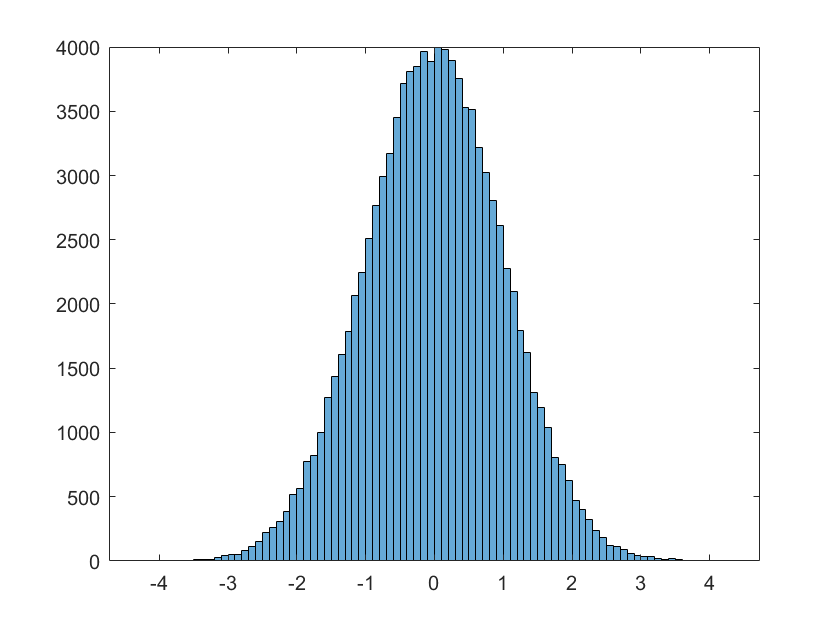

v = randn(1,100000);
histogram(v);

Berenchnen Sie den Mittelwert (mean) sowie die Standardabweichung (std) von v.

m = mean(v);
stdev = std(v);

Führen Sie die Transformationen v1 = v*2 + 5, v2 = v*0.5 - 3 aus und zeichnen Sie ein Diagramm, welches sowohl das Histrogramm von v und v1, v2 darstellt. Achten Sie darauf, dass in allen Histogrammen dieselbe Anzahl bins verwendet wird! (histogram(v, 100))

Bestimmen Sie den Mittelwert sowie die Standardabweichung der zufallsvariablen v1 und v2. Was stellen Sie fest bezgl. der obigen Transformationen?

Was bewirkt die Standardabweicung?

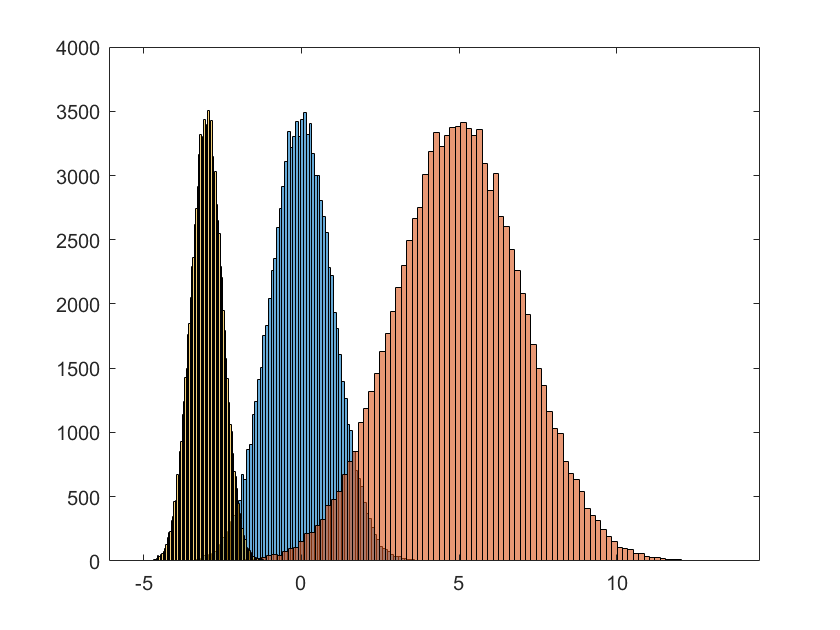

v1 = v.*2 + 5;
v2 = v.*.5 -3;
histogram(v,100);
hold on;
histogram(v1,100);
histogram(v2, 100);
hold off;

## Korrelation:

Zeichenen Sie einen Scatterplot von v und v1 und im selben Diagramm von v und v2. Entspricht das Diagramm ihren Erwartungen?

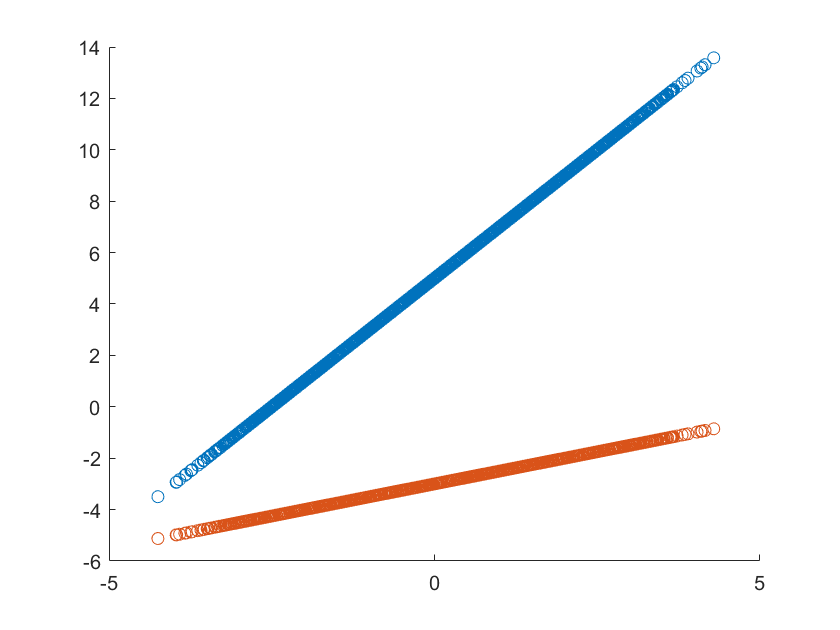

scatter(v, v1); 
hold on;
scatter(v, v2);
hold off;

Definieren Sie einen weiteren vector v3 mit gleich vielen Datenelement wie v. Verwenden Sie ebenfalls randn und zeichnen Sie einen Scatterplot von v und v3. Entspricht das Diagramm ihren Erwartungen?

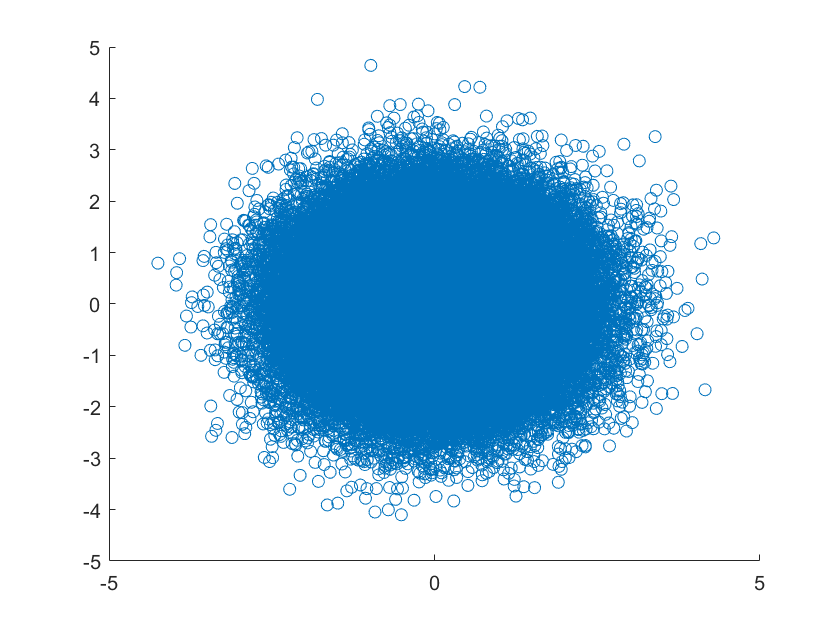

[dim, sz] = size(v);
v3 = randn(1, sz);
scatter(v, v3);

Ein Mass, wie stark zwei Variablen voneinander "abhängen" ist der sogenannte Korrellationskoeffizient. Berechnen Sie den Korrellationskoeffizient zwischen V und V2 sowie zwischen V und V3 (Funktion corrcoef(x,y)).

cm1 = corrcoef(v,v2);
cm2 = corrcoef(v, v3);

In der Praxis wird man in der Regel weder vollkommen korrelierte noch vollkommen unkorrelierte Daten haben. Um eine solche Situation zu simulieren erstellen wir einen Vektor v4 mit [1:100] sowie einen Vektor v5 mit v5 = 4 + v4*.3 + randn(1,100).*2 und einen Vektor v6 mit v6 = 3 - v4 * 0.75 + randn(1,100).*2. Zeichen Sie je einen Scatterplot mit diesen Daten.

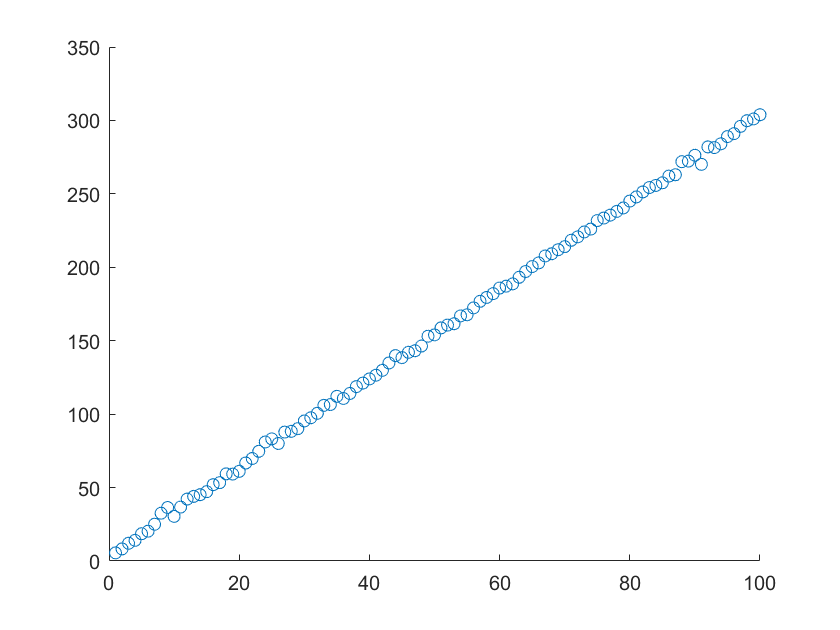

v4 = 1:100;
v5 = 4 + v4.*3 + randn(1,100).*2;
v6 = 3 - v4.*0.75 + randn(1,100).*2;
scatter(v4, v5);

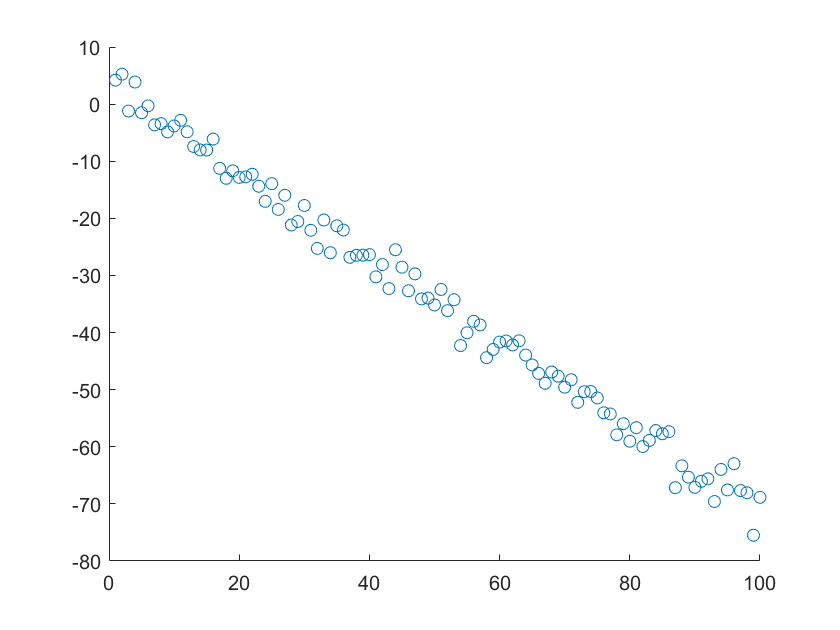

scatter(v4, v6);

Berechnen Sie die Correlationscoeffizienten zwischen v4 und v6 sowie zwischen v4 und v5. Was bedeutet ein negativer Korrellationscoeffizient?

cm3 = corrcoef(v4,v5);
cm4 = corrcoef(v4,v6);

Berechnen Sie mit der Funktion fitlm(v4, v6) eine regressionsgerade. weisen sie das Ergebnis einer Variablen 'model' zu. Schauen Sie sich im Workspace diese Variable an insbesonder das Property 'Coefficients'. In der Spalte 'Estimate' finden wir die berechneten Schätzwerte für die Schnittstelle mit der y Achse bei x = 0 (=**Intercept**) sowie die Steigung der Geraden (=**x1**).

Zeichen Sie eine Scatterplot mit den Variablen v4 und v6. Zeichnen Sie in demselben Diagramm eine Gerade mit y = I**ntercept** + **x1***x. Wie passt das?

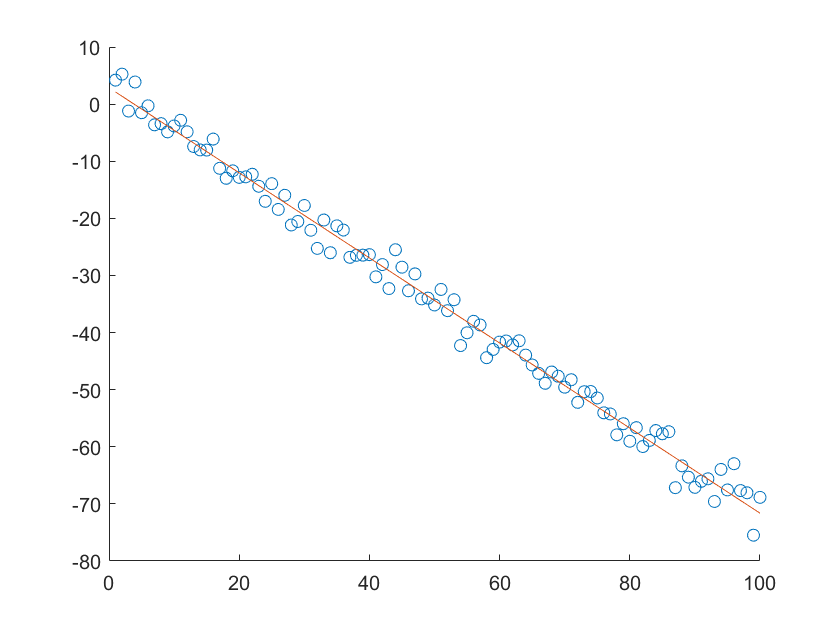

model1 = fitlm(v4, v6);
intercept = model1.Coefficients.Estimate(1);
slope = model1.Coefficients.Estimate(2);
estimate = intercept + slope * v4;
scatter(v4, v6);
hold on;
plot( v4, estimate );
hold off;

Geben Sie die Variable model in einem Diagramm aus (plot(model)).

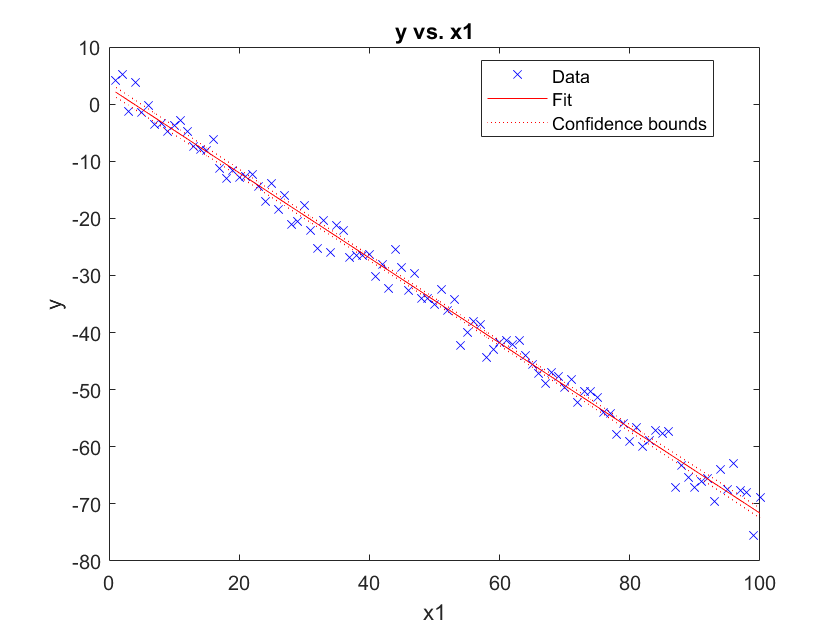

plot(model1);

Lesen sie die Datei Geburten_Stoerche.csv ein und berechnen Sie den den Korrellationskoeffizienten sowie ein modell mit fitlm. Was ist ihr Kommentar?

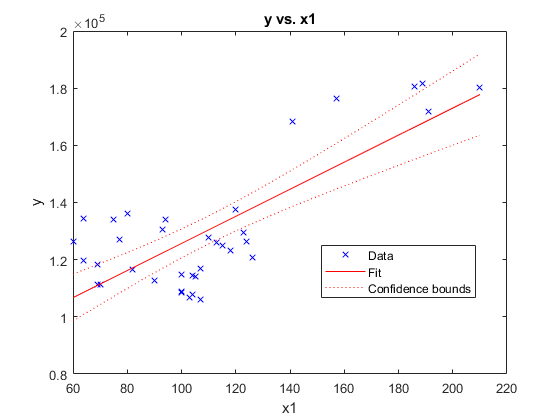

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["Jahr", "Geburten", "Stoerche"];
opts.VariableTypes = ["int16", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data 
data = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\Stoerche_Geburten.csv", opts);
g = data.Geburten;
s = data.Stoerche;
corrcoef(s,g);
model = fitlm(s,g);
plot(model);